## Ann Fiegel - Class Project Part 1

Module 1, Project Bank Question 1

Billing Programs

Plan A: f(x)= 15x + 25

Plan B: g(x) = 

                12x + 40     when x < 400

                14x + (40 - 2*400)      when x > 400

Where x is energy usage in kWh

Part 1) Implement both models for x = 0:20:800


x = [0:20:800]; % creating the array for the x values.

function planA = f(x) % creating a function for the for the first billing plan that calculates the values for all values of x. 
    planA = 15.*x + 25; % stating what the function to be used for the first billing plan is. 
end % ending the function which calculates the values for plan A.

function planB = g(x) % creates a function for the second billing plan that calculates the values for all values of x. 
n = numel(x); % stating that the return of this function needs to be an array of the same size as x. 
planB = zeros(size(x)); % stating that the ruturn plan B, will start as a zero vecor of size x, then be filled in using the following loop. 
for k = 1:n % loop for k which holds values one through n.
    xi = x(k); % k calls specific values from x to calculate values for the planB array.
    if xi < 400 % plan B is a peicewise fucntion, so this is specifying the first part of the peicewise fucntion. 
        planB(k) = 12*xi + 40; % stating the first part of the peicewise funtion for values of planB to be calculated. 
    else % if not the fisrt part of the peicewise functin, then the secon part. 
        planB(k) = 14*xi + (40 - 2*400); % stating the second part of the peicewise function for the remainder of the values of palnB to be calculated. 
    end % end of if statements
end % end of for loop
end % end of function

planA = f(x) % calling plan A to be calculated. 

planA =           25         325         625         925        1225        1525        1825        2125        2425        2725        3025        3325        3625        3925        4225        4525        4825        5125        5425        5725        6025        6325        6625        6925        7225        7525        7825        8125        8425        8725        9025        9325        9625        9925       10225       10525       10825       11125       11425       11725       12025


planB = g(x) % callling plan B to be calculated. 

planB =           40         280         520         760        1000        1240        1480        1720        1960        2200        2440        2680        2920        3160        3400        3640        3880        4120        4360        4600        4840        5120        5400        5680        5960        6240        6520        6800        7080        7360        7640        7920        8200        8480        8760        9040        9320        9600        9880       10160       10440


Part 2) Graph both lines on the same plane

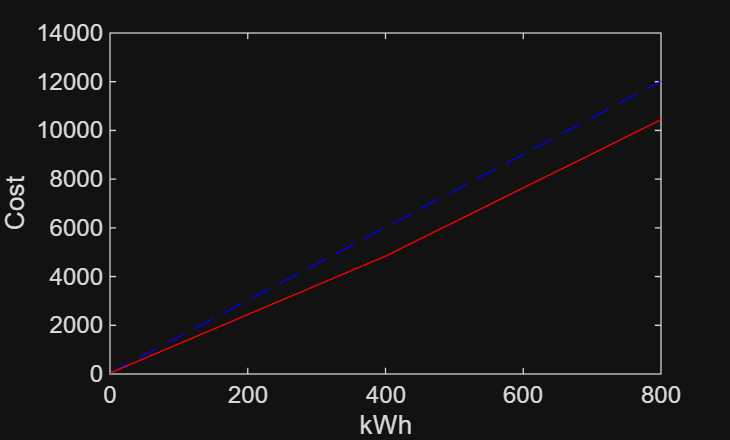


plot(x, planA, 'b--') % plotting the graph of the plan A values with a blue dotted line. 
hold on % making both plots on the same graph. 
plot(x, planB, 'r-') % plotting the graph of plan B with a red continuous line. 
xlabel('kWh') % labeling the X axis
ylabel('Cost') % labeling the Y axis
hold off % nothing elce needs to go on the same graph so the hold is taken off. 

Part 3) Determine the usage levels where plan A and plan B are the same cost


% Exact equality (works when values are exact integers or exact matches)
equalMask = (planA == planB);      % makeign certain that planA and plan B have arrays the same size as x
idx = find(equalMask);             % finding the values where plan A and plan B are equal. 
x_equal = x(idx);                  % x values where plans match

% Displays the vlaue where plan A and plan B are equal. 
fprintf('Matches at %d points\n', numel(idx)) 

Matches at 0 points


disp(x_equal)


Part 4) Create a table of at least ten rows for the usages


x_col     = x(:); % transform x from a row vector to a column vector
planA_col = planA(:); % transform planA from a row vector to a column vector
planB_col = planB(:); % transform planB from a row vector to a colunm vector

UsageTable = table(x_col, planA_col, planB_col, ... % creating a table with x, planA, and plan B
    'VariableNames', {'x', 'planA', 'planB'});      % and labeling the columns. 

disp(UsageTable)  % display the table

     x     planA    planB
    ___    _____    _____

      0       25       40
     20      325      280
     40      625      520
     60      925      760
     80     1225     1000
    100     1525     1240
    120     1825     1480
    140     2125     1720
    160     2425     1960
    180     2725     2200
    200     3025     2440
    220     3325     2680
    240     3625     2920
    260     3925     3160
    280     4225     3400
    300     4525     3640
    320     4825     3880
    340     5125     4120
    360     5425     4360
    380     5725     4600
    400     6025     4840
    420     6325     5120
    440     6625     5400
    460     6925     5680
    480     7225     5960
    500     7525     6240
    520     7825     6520
    540     8125     6800
    560     8425     7080
    580     8725     7360
    600     9025     7640
    620     9325     7920
    640     9

Part 5) Write a reccomendation of wheather to use plan A or plan B.

Given the different prices per kilowatt hour for useages between the two plabs, it is advisable to use plan B due to the fact that it is cheaper per kilowatt hour than plan A. 